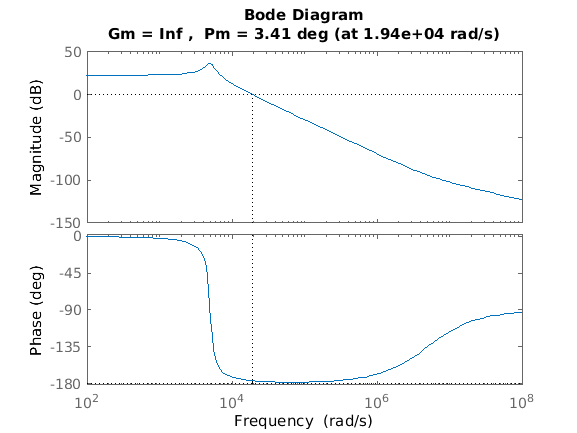

clc;
clear;

% Buck Converter Constants

Vo = 5;
Vin = 14;

L = 4e-3;
C = 10e-6;

r = 0.02;
R = 100;

f_s = 30e3;

s = tf('s');
buck = (Vin/(L*C)) * ((1 + s*r*C) / (s^2 + s*(1/(R*C) + r/L) + 1/(L*C)));
margin(buck)

[Gm,Pm,Wcg,Wcp] = margin(buck);

% Controller Values
Ri = 10e3

Ri = 10000

Kp = 0.1

Kp = 0.1000

Rf = Kp*Ri

Rf = 1000

Cf = 1/(Rf*(Wcp)*1e-2)

Cf = 5.1677e-06

Ki = 1/(Ri*Cf)

Ki = 19.3510

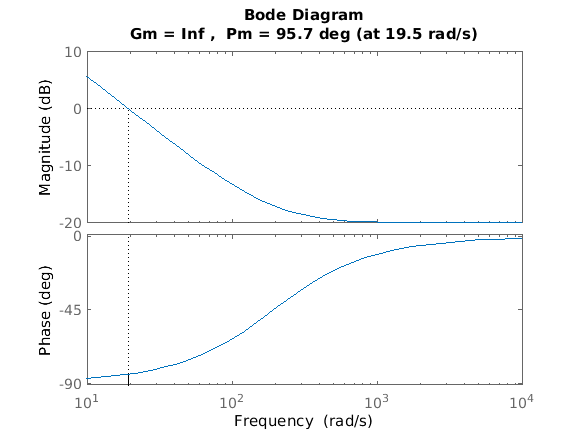

controller = (Rf + (1/(Cf*s)))/(Ri);
margin(controller)

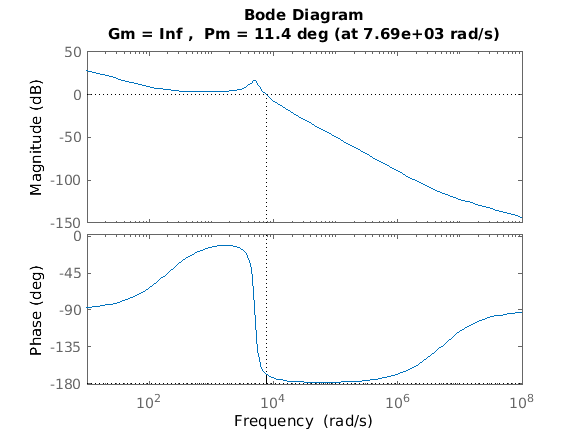

margin(controller*buck)